#### EXERCICI ENTREGABLE

Para calcular la diferencia de errores hemos graficado la diferencia entre los angulos calculados por los operadores y el angulo de rotacion original.

Grafica Sobel 3x3:

I = double(zeros(101));

for i=50:101
    I(i,:) = 255;
end

result = zeros(1,900);
sobelV = sobelkernel(3);
sobelH = sobelV';

index = 1;
for theta = 0:0.1:90
    
    A = imrotate(I, theta,'bicubic','crop');
    A = imfilter(A,fspecial('gaussian',10,2));
    
    Ax = imfilter(A, sobelH);
    Ay = imfilter(A, sobelV);
    
    alpha = mod((atan2(Ay(50,50),Ax(50,50)))*180/pi+180, 360);
    result(1,index) = abs(theta - alpha);

    index = index + 1;
end

MaxError = max(result)

MaxError = 0.2522

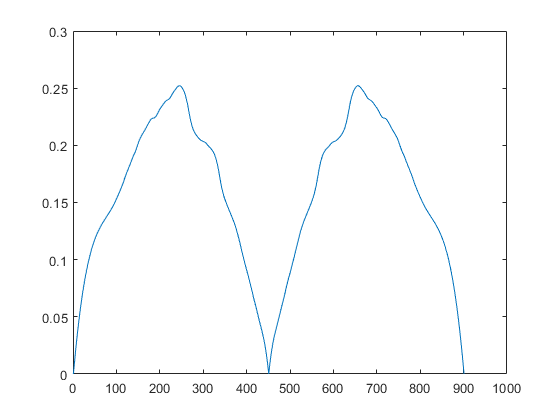

plot(result);

Grafica Sobel 5x5:

I = double(zeros(101));

for i=50:101
    I(i,:) = 255;
end

result = zeros(1,900);

sobelV = sobelkernel(5);
sobelH = sobelV';

index = 1;
for theta = 0:0.1:90
    
    A = imrotate(I, theta,'bicubic','crop');
    A = imfilter(A,fspecial('gaussian',10,2));
    
    Ax = imfilter(A, sobelH);
    Ay = imfilter(A, sobelV);
    
    alpha = mod((atan2(Ay(50,50),Ax(50,50)))*180/pi+180, 360);
    result(1,index) = abs(theta - alpha);

    index = index + 1;
end

MaxError = max(result)

MaxError = 0.2120

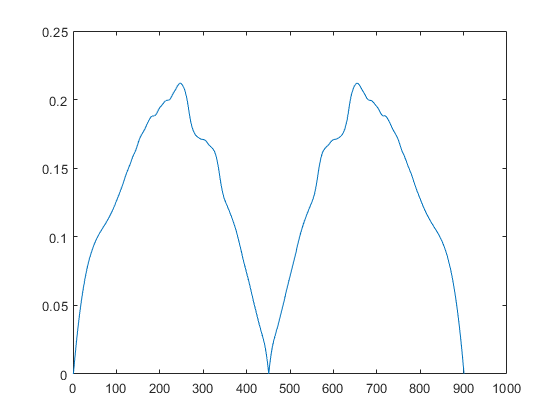

plot(result);

Grafica Prewitt 5x5:

I = double(zeros(101));

for i=50:101
    I(i,:) = 255;
end

result = zeros(1,901);

kernelH = [ 2  2  4  2  2; 1  1  2  1  1; 0  0  0  0  0; -1 -1 -2 -1 -1; -2 -2 -4 -2 -2];
kernelV = kernelH';

index = 1;
for theta = 0:0.1:90
    
    A = imrotate(I, theta,'bicubic','crop');
    A = imfilter(A,fspecial('gaussian',10,2));
    
    Ax = imfilter(A, kernelH);
    Ay = imfilter(A, kernelV);
    
    alpha = mod((atan2(Ay(50,50),Ax(50,50)))*180/pi+180, 360);
    result(1,index) = abs(theta - alpha);

    index = index + 1;
end

MaxError = max(result)

MaxError = 0.6940

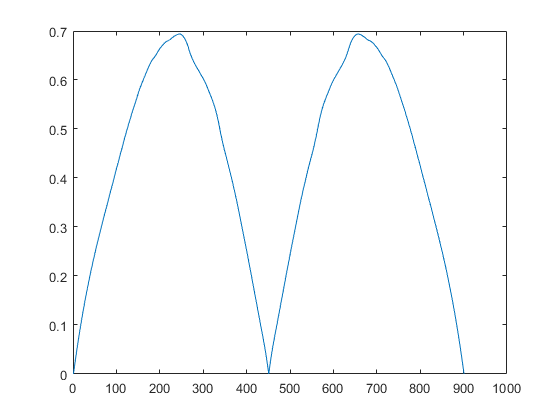

plot(result);

Grafica Foid&Simonelli 5x5:

I = double(zeros(101));

for i=50:101
    I(i,:) = 255;
end

result = zeros(1,900);

k  = [0.030320  0.249724  0.439911  0.249724  0.030320];
d  = [0.104550  0.292315  0.000000 -0.292315 -0.104550];

index = 1;
for theta = 0:0.1:90
    
    A = imrotate(I, theta,'bicubic','crop');
    A = imfilter(A,fspecial('gaussian',10,2));
    
    Ax = conv2(d,k,A,'same');
    Ay = conv2(k,d,A,'same');
    
    alpha = mod((atan2(Ay(50,50),Ax(50,50)))*180/pi, 360);
    result(1,index) = abs(theta - alpha);

    index = index + 1;
end

MaxError = max(result)

MaxError = 0.0404

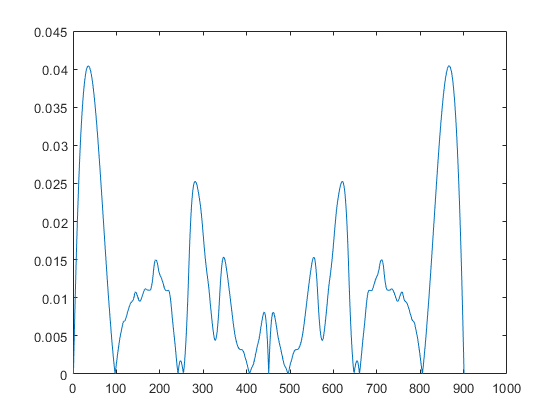

plot(result);

Tabla de errores maximos: